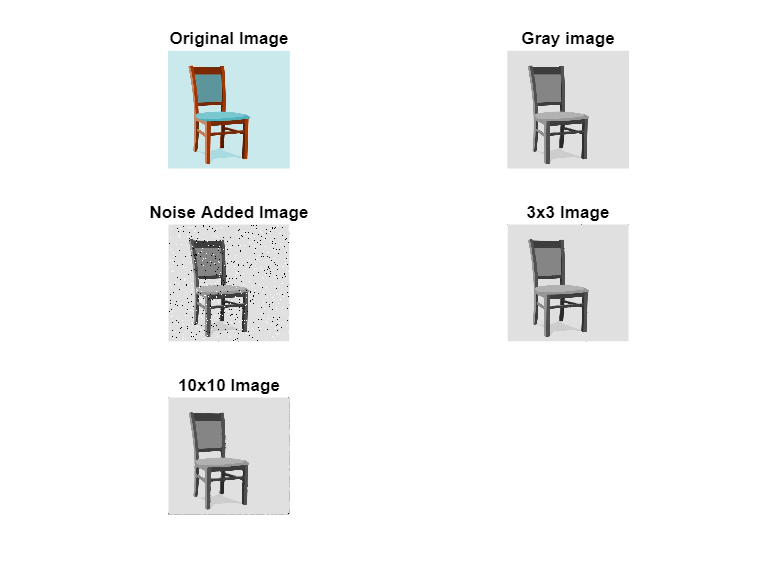

% Implementation of image smoothening filters (Mean and Median filtering of an Image)

clc;

i=imread("apple image.jpg");


% Median filters
subplot(3,2,1);
imshow(i);
title('Original Image');

subplot(3,2,2);
w=rgb2gray(i);
imshow(w);
title('Gray image');

subplot(3,2,3);
j=imnoise(w,'salt & pepper',0.05);
imshow(j);
title('Noise Added Image')

subplot(3,2,4);
b=medfilt2(j,[3,3]);
imshow(b);
title('3x3 Image');

subplot(3,2,5);
c=medfilt2(j,[10,10]);
imshow(c);
title('10x10 Image');

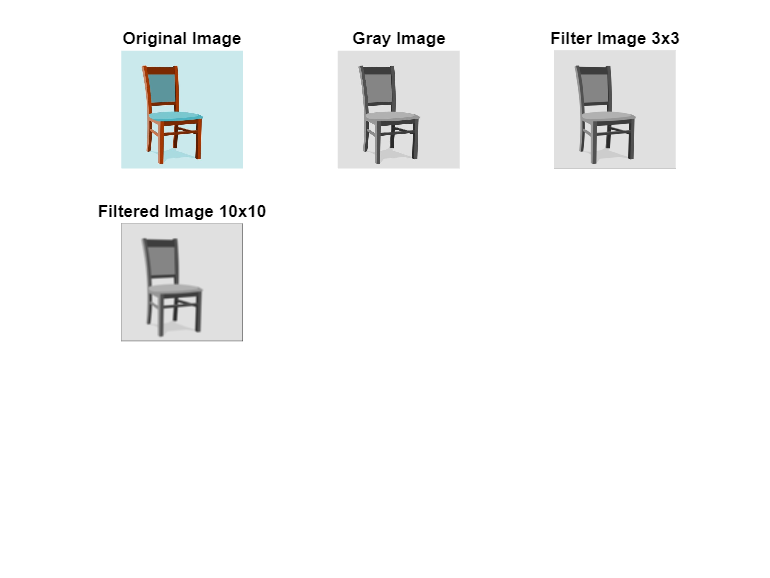


% Mean Filter and average filter
figure

subplot(3,3,1);
imshow(i);
title('Original Image');

subplot(3,3,2);
imshow(w);
title('Gray Image');

subplot(3,3,3);
f1=fspecial('average',[3,3]);
b1=imfilter(w,f1);
imshow(b1);
title('Filter Image 3x3');

subplot(3,3,4);
f2=fspecial('average',[10,10]);
b2=imfilter(w,f2);
imshow(b2);
title('Filtered Image 10x10');

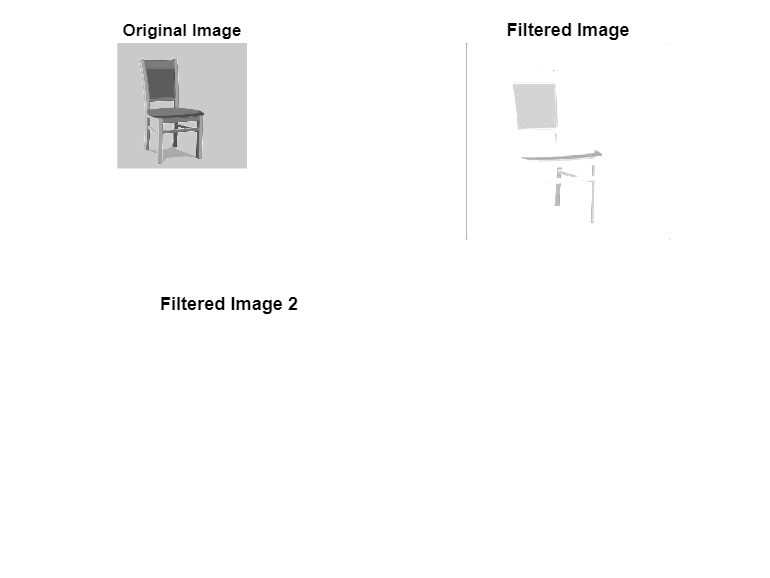

% Implementation of filter using convolution
figure


a=[0.001 0.001 0.001; 0.001 0.001 0.001; 0.001 0.001 0.001];
b=[0.005 0.005 0.005; 0.005 0.005 0.005; 0.005 0.005 0.005];

subplot(3,3,1);
i2=i(:,:,1);
imshow(i2);
title('Original Image');


subplot(2,2,2);
R=conv2(a,i2);
imshow(R);
title('Filtered Image');


subplot(2,2,3);
R1=conv2(b,i2);
imshow(R1); 
title('Filtered Image 2');